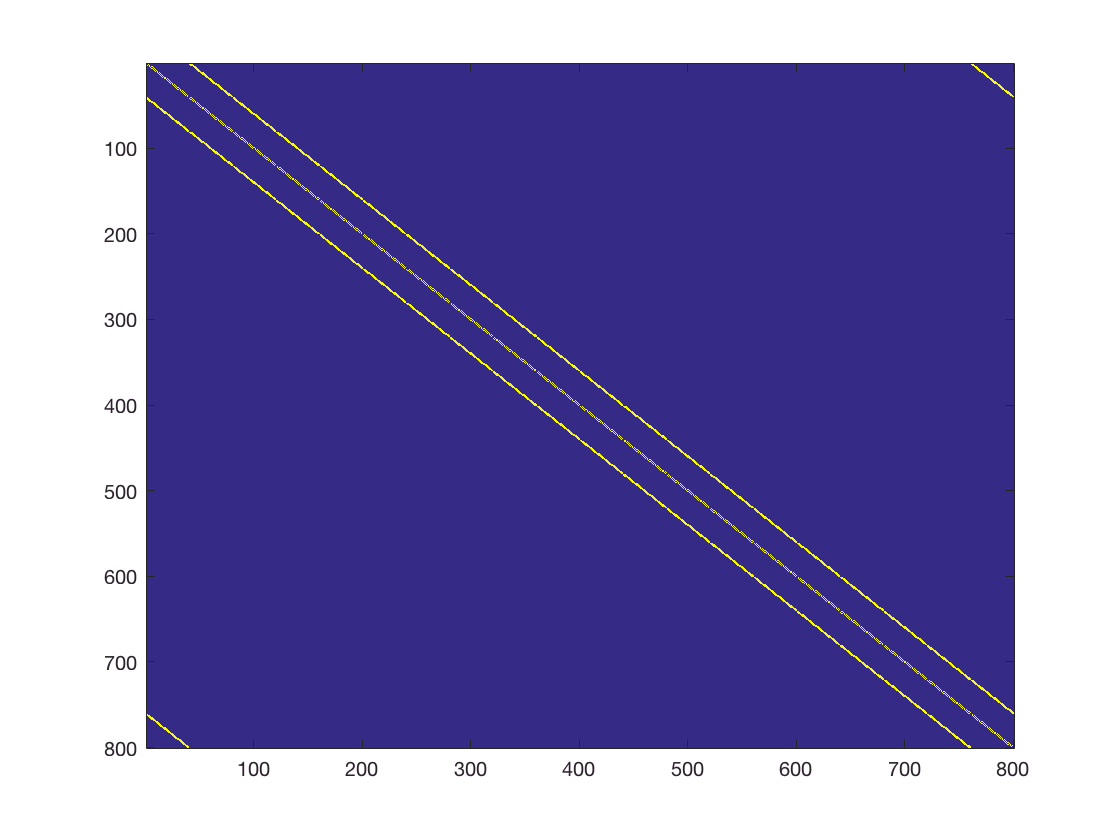

% Generate the tube adjacency matrix
% i.e. geometric constrain

% ADD first, second neighbors

m=20;
n=40;
p0=1;
sigma_x=5;
sigma_y=10;

A_tube=M_tube(m,n);

imagesc(A_tube);

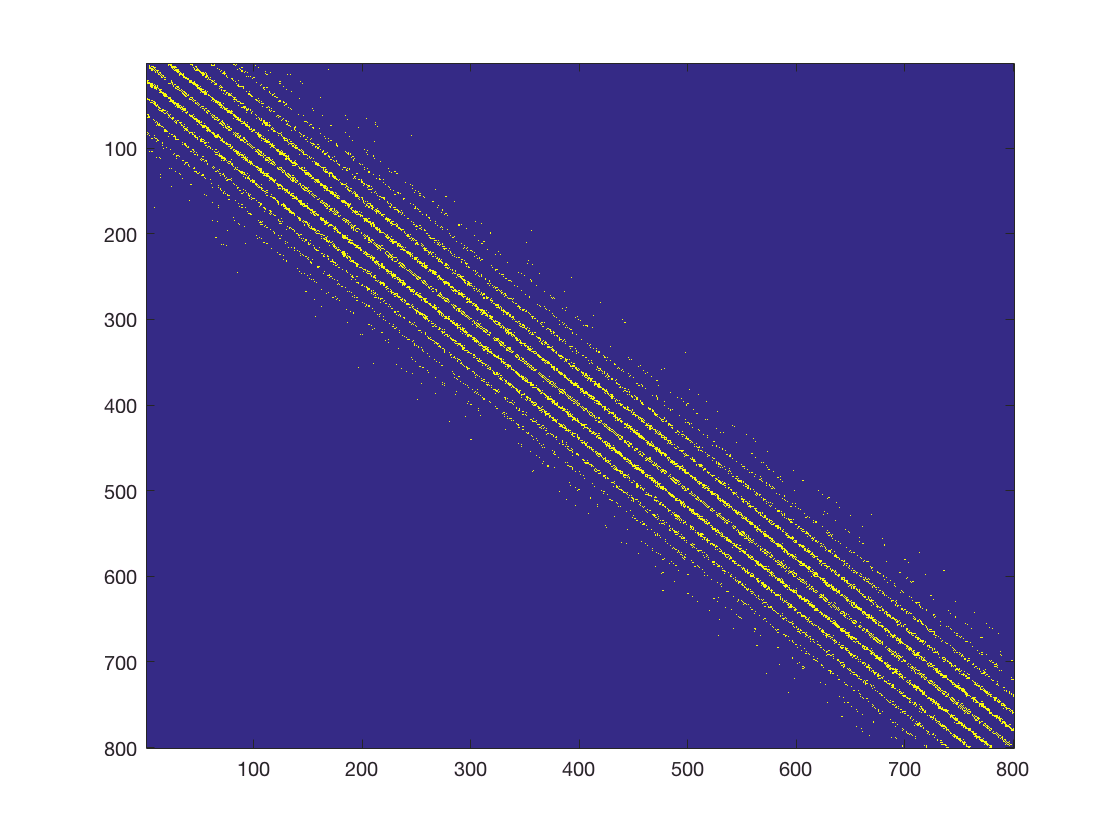

% Generate the connectivity matrix from given distribution decrease
% Euclidean distance, p=p0*exp(-(x-i)^2/sigma_x -(y-j)^2/sigma_y);
% AUTAPSES REMOVED!

% i.e. decrease of connection probability constrain

[A_pocket,A_prob]=M_pocket(m,n,p0,sigma_x,sigma_y);
imagesc(A_pocket);

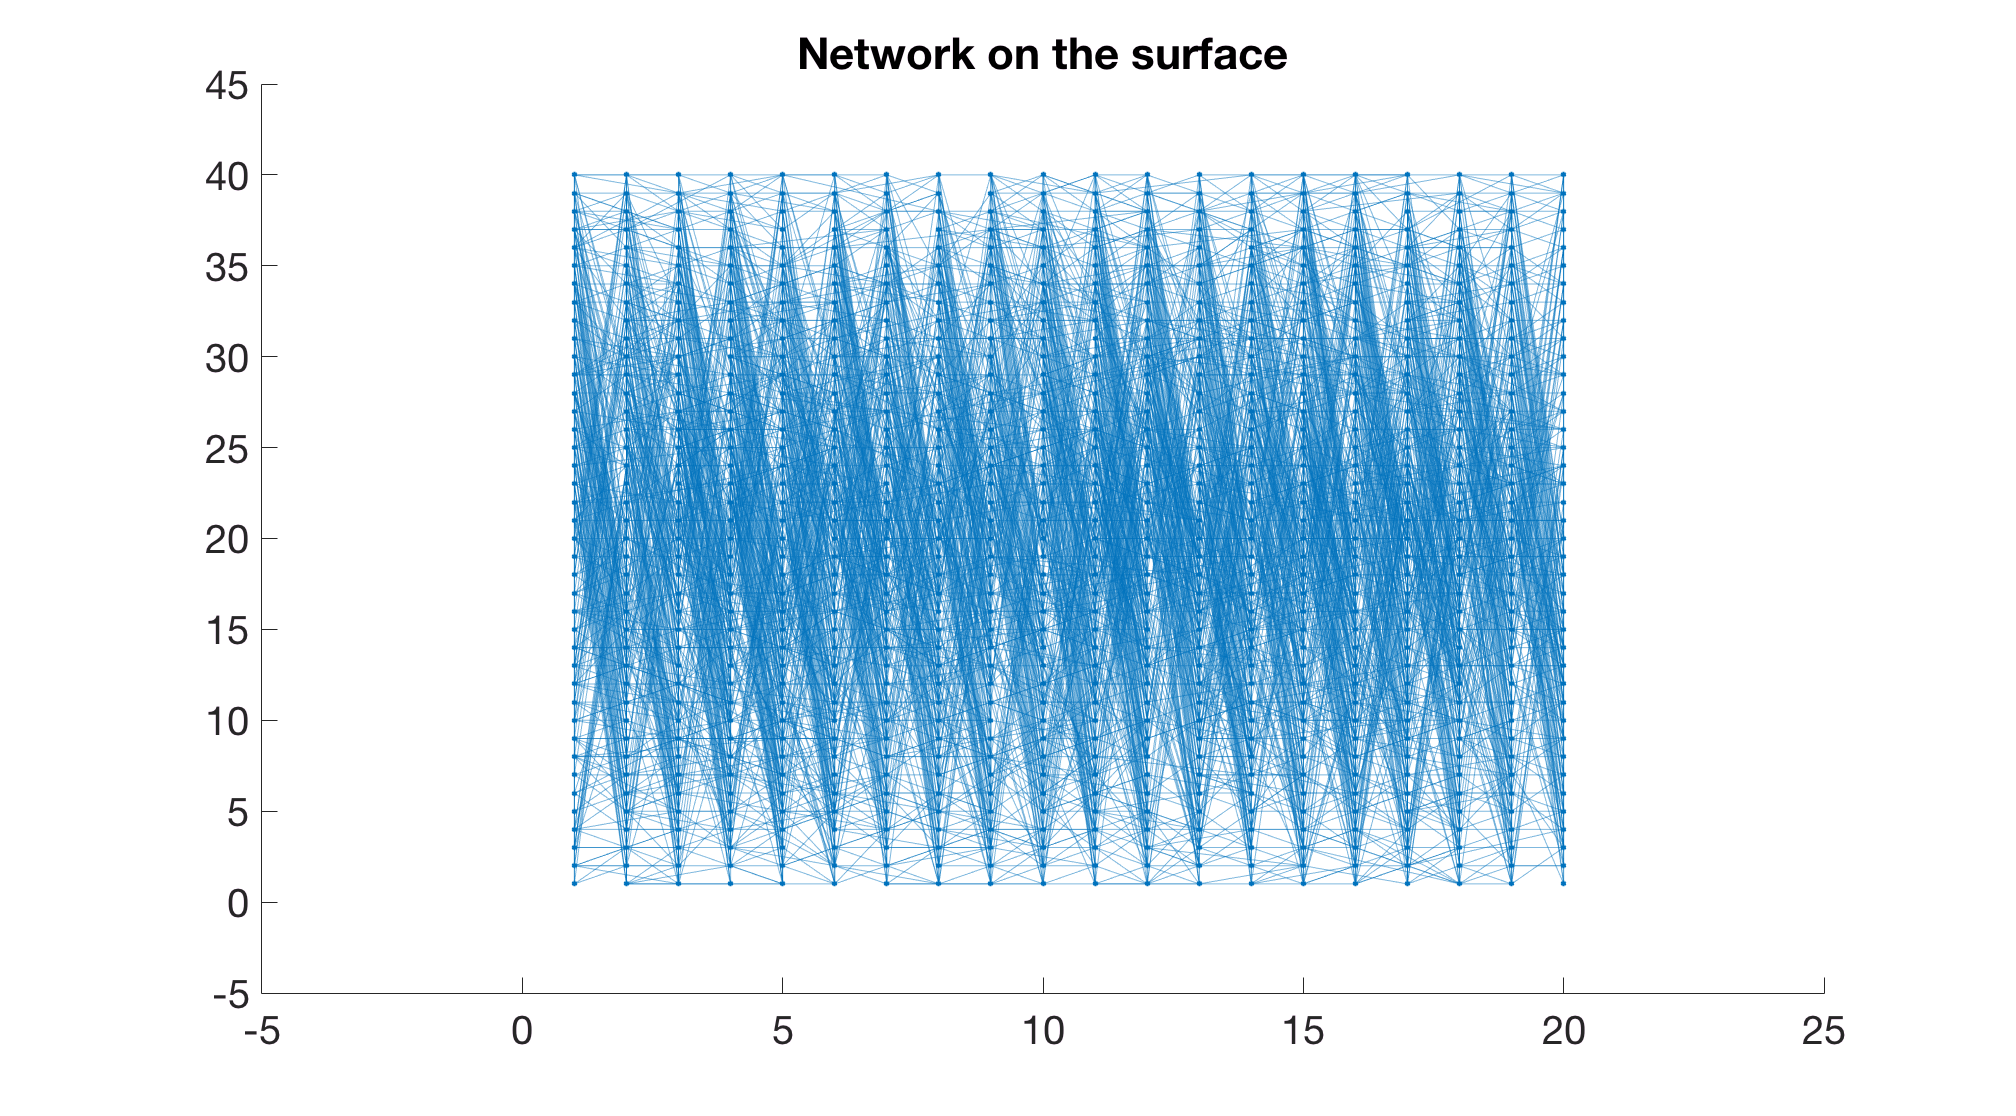

%% Generates the plot of the graph with the input stimuli PROBLEM - NOT ALL FIRED CELLS ARE SHOWN!!!

% graph parameters

figure('units','normalized','outerposition',[0 0 0.7 0.7]); % show figure window

%A_graph=graph(A_ind_dist);
A_graph=graph(A_pocket);

%h=plot(A_graph,'Layout','force');  % force graph

[X,Y]=meshgrid(1:m,1:n);        
x=reshape(X,[1,m*n]);
y=reshape(Y,[1,m*n]);
h=plot(A_graph,'Xdata',x,'Ydata',y);    %handle for the graph plot
%xlim([-6 20]);
%ylim([0 53]);

box off

%highlight(h,firings(:,2),'Markersize',7,'Nodecolor','r')    % firing ensemble
%highlight(h,stim_1,'Markersize',7,'Nodecolor','g')          % stimulated cells

title('Network on the surface')
set(gca,'Fontsize',20)

% Generate and plot the corresponding graph

A_graph=biograph(A_ind_dist);

view(A_graph)

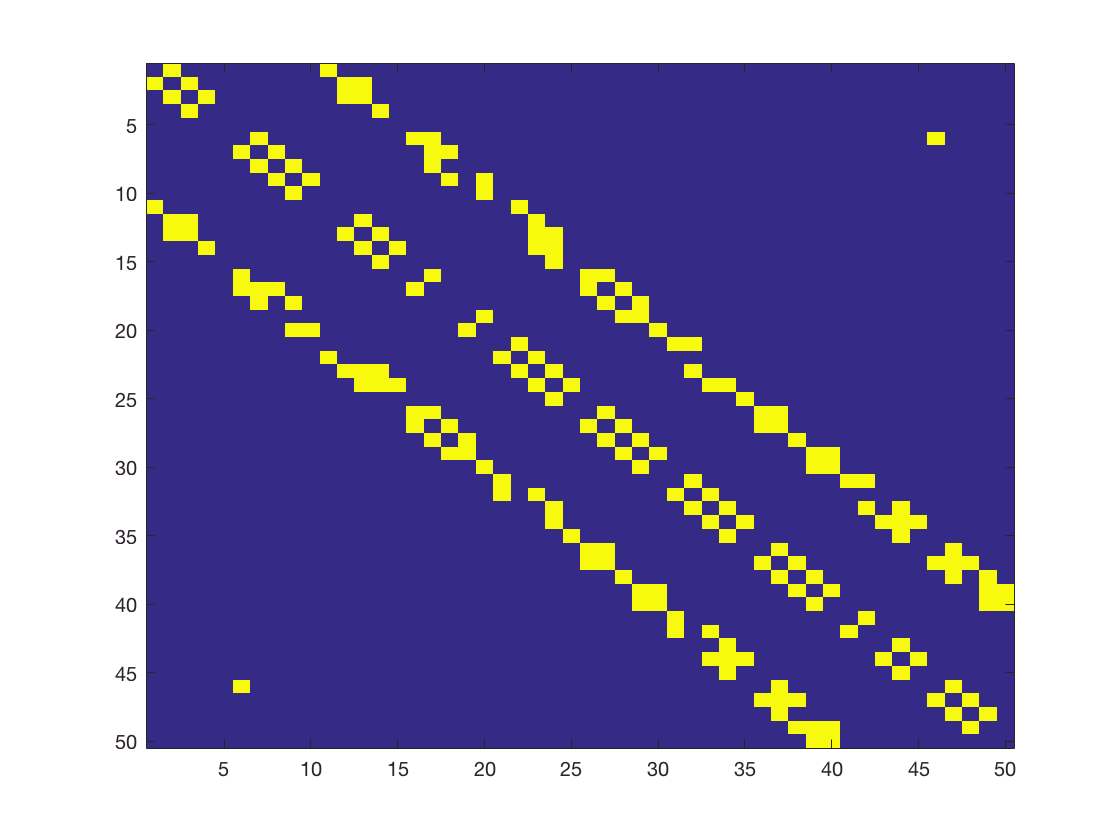

% Element-wise multiplication of both matrixies
% First order neighbors

A_total=A_tube.*A_ind_dist;
imagesc(A_total)